N = 10;
M = 200;
deltaT = 1/M;
deltaX = 1/N;
lambda = N*N/M;

x = linspace(0, 1, N + 1);
t = linspace(0, 1, M + 1);

[X, T] = meshgrid(x, t);

x = x*deltaX;
t = t*deltaT;

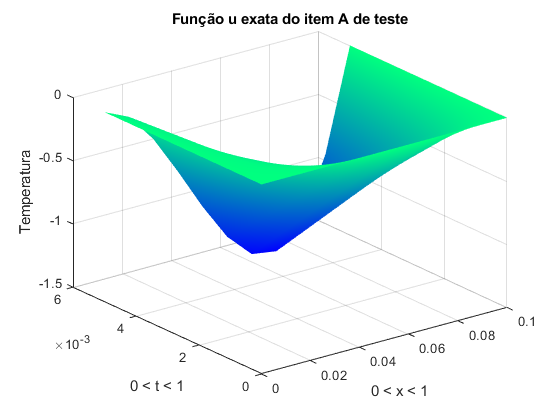

% 1A Teste
uReal = (10 .* X .* X .* (X - 1) .* T);

figure(1)
surf(x, t, uReal)
title('Função u exata do item A de teste')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('winter')
shading interp

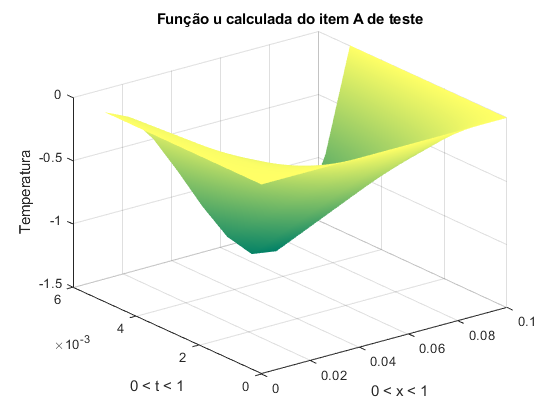


figure(2)
R1aT = readmatrix('Output1ATeste.txt');
R1aT(:,end) = [];
surf(x, t, R1aT)
title('Função u calculada do item A de teste')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('summer')
shading interp

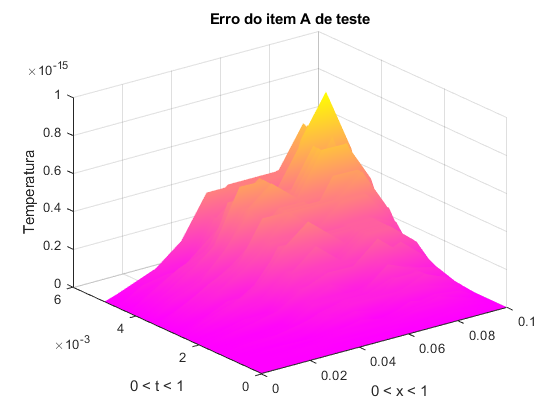


figure(3)
erro1aT = readmatrix('Erro1ATeste.txt');
erro1aT(:,end) = [];
surf(x, t, erro1aT)
title('Erro do item A de teste')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('spring')
shading interp

syms x_var t_var

u = (10 * x_var * x_var * (x_var - 1) * t_var)

$$u = 10\,t_{\mathrm{var}}\,{x_{\mathrm{var}}}^{2}\,\left(x_{\mathrm{var}}-1\right)$$

	
C1 = diff(u, t_var, 2)/2

$$C1 = 0$$

C2 = diff(u, x_var, 4)/24

$$C2 = 0$$

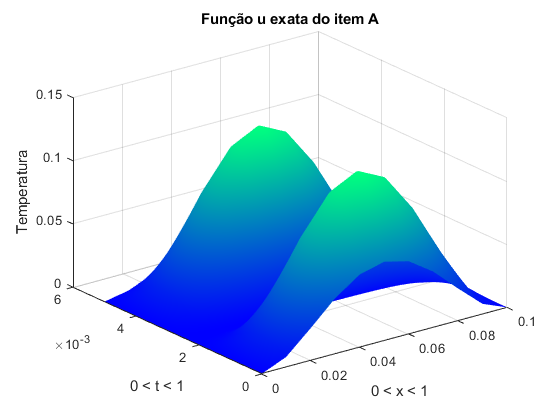

% 1A Real
uReal = ((1 + sin(10 .* T)) .* X .* X .* (1 - X) .* (1 - X));

figure(1)
surf(x, t, uReal)
title('Função u exata do item A')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
shading interp

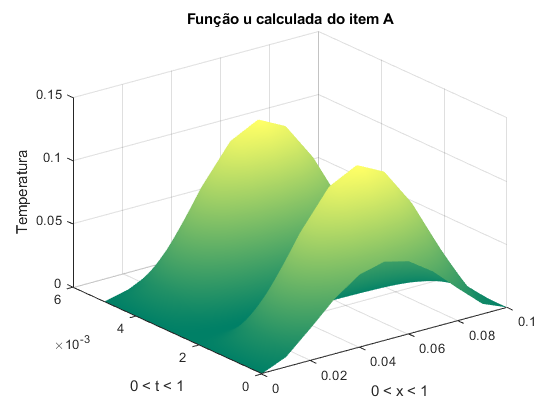


figure(2)
R1a = readmatrix('Output1A.txt');
R1a(:,end) = [];
surf(x, t, R1a)
title('Função u calculada do item A')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('summer')
shading interp

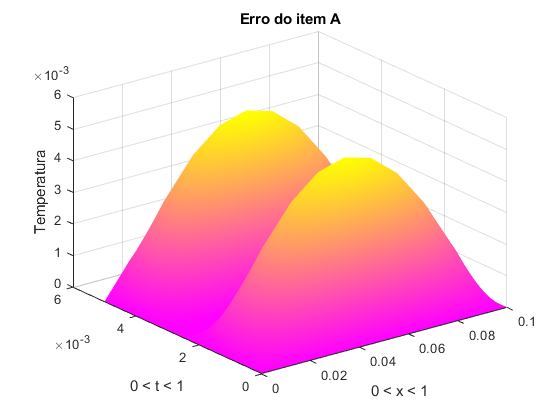


figure(3)
erro1a = readmatrix('Erro1A.txt');
erro1a(:,end) = [];
surf(x, t, erro1a)
title('Erro do item A')
xlabel('0 < x < 1')
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('spring')
shading interp

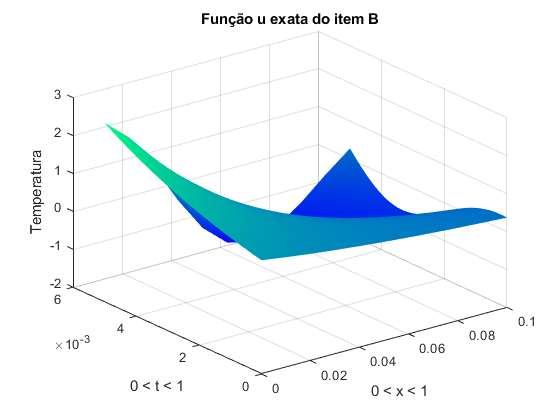

% 1B
uReal = (exp(T - X) .* cos(5 .* T .* X));

figure(1)
surf(x, t, uReal)
title('Função u exata do item B')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
shading interp

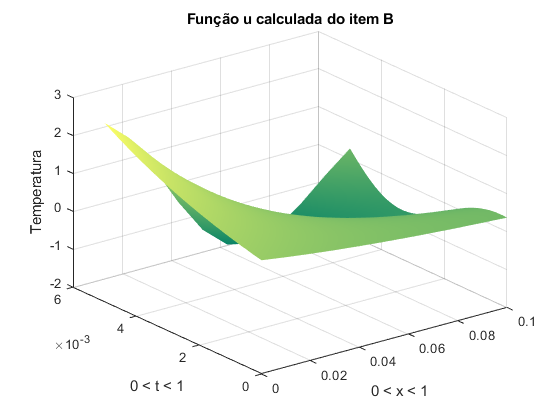


figure(2)
R1b = readmatrix('Output1B.txt');
R1b(:,end) = [];
surf(x, t, R1b)
title('Função u calculada do item B')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('summer')
shading interp

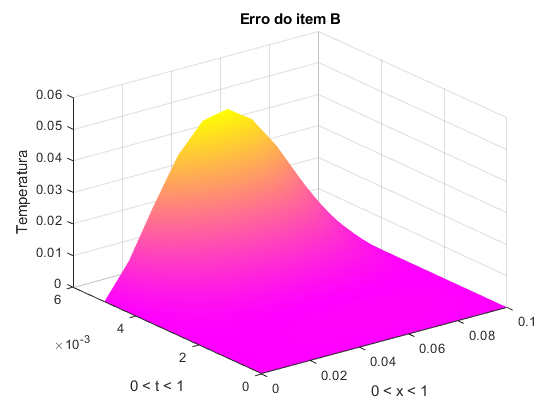


figure(3)
erro1b = readmatrix('Erro1B.txt');
erro1b(:,end) = [];
surf(x, t, erro1b)
title('Erro do item B')
xlabel('0 < x < 1')
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('spring')
shading interp

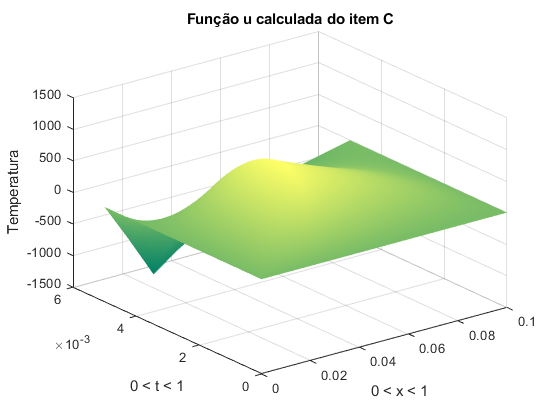

% 1C

R1c = readmatrix('Output1C.txt');
R1c(:,end) = [];
surf(x, t, R1c)
title('Função u calculada do item C')
xlabel('0 < x < 1') 
ylabel('0 < t < 1')
zlabel('Temperatura')
colormap('summer')
shading interp